files = dir("load_disp_refine\*.csv")

files = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


[~, reindex] = sort( str2double( regexp( {files.name}, '\d+', 'match', 'once' )))

reindex =      1     2     3     4     5     6     7


files = files(reindex)

files = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


%files = files(1:end-1)
max_disp = zeros(length(files),1);
for i=1:length(files)
    file = files(i,:);
    data = readmatrix(strcat(file.folder,"\", file.name));
    max_disp(i) = max(data(:,2));
end
max_disp

max_disp =     8.2268
   11.3284
   13.7069
   16.5676
   19.3002
   21.2062
   21.2383


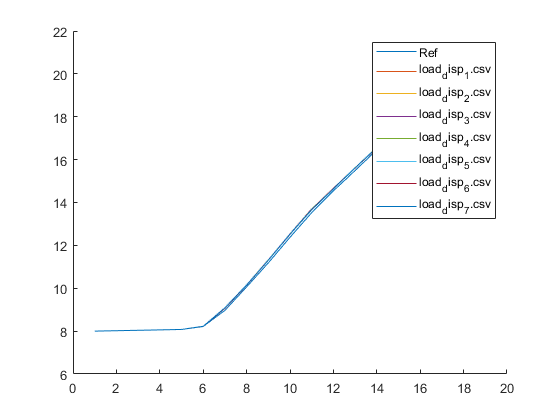

close all;
figure()
hold on;
file = files(length(files)-1,:);
data_value = readmatrix(strcat(file.folder,"\", file.name));
data_value = readmatrix("load_disp_real.csv");
plot(data_value(:,1),data_value(:,2),'DisplayName',"Ref");
for i = 1:length(files)
    file = files(i,:);
    data = readmatrix(strcat(file.folder,"\", file.name));
    plot(data(:,1),data(:,2),'DisplayName',file.name);
    drawnow
    pause(0.1);
end
legend()

close all;
figure()
hold on;
%file = files(length(files),:);
data_value = readmatrix("load_disp_real.csv");
ref_disp = max(data_value(:,2))

ref_disp = 21.1388

for i = 1:length(files)
    file = files(i,:);
    data = readmatrix(strcat(file.folder,"\", file.name));
    lstps = length(data);
    plot(data(:,1),100*abs(data(:,2) - data_value(1:lstps,2))/ref_disp,'DisplayName',regexp( file.name, '\d+', 'match', 'once'));
end
xlabel("Load-step")
ylabel("Displacement error %")
lgd  = legend()

lgd =   Legend (1, 2, 3, 4, 5, 6, 7) with properties:

         String: {'1'  '2'  '3'  '4'  '5'  '6'  '7'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7827 0.6175 0.1036 0.2833]
          Units: 'normalized'

  Show all properties


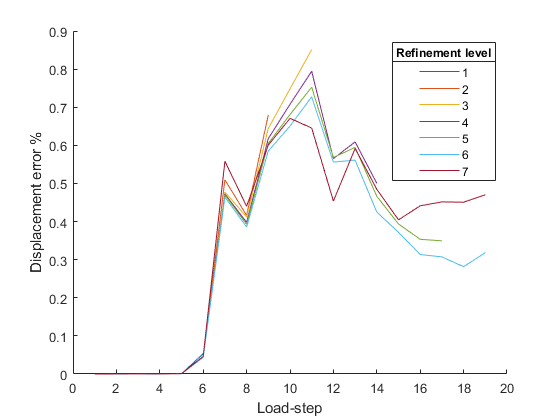

lgd.Title.String = 'Refinement level';

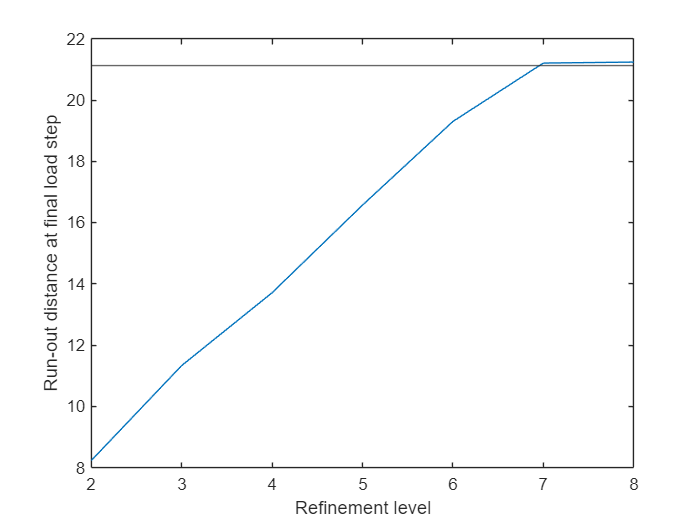

figure()
mps = (2:(length(files)+1));
plot(mps,max_disp)
yline(ref_disp);
xlabel("Refinement level");
ylabel("Run-out distance at final load step");